# Shift-invariant PSF examples

This script shows how to use shift-invariant optics with Gaussian, Lorentzian and Pillbox point spread functions (PSFs).

The script calculates the impact of these PSFs on a simple grid scene, visualizing the outcome in an optical image window.

PSFs are generated using *`siSynthetic`*, which supports various types and introduces wavelength-dependent chromatic aberrations. Read the siSynthetic function to learn how to create optics using a defined PSF.  The utility *ieSaveSIDataFile *may also be helpful.

**See also:** siSynthetic, ieSaveSIDataFile

**Formatting notes:**

- Export to HTML in the code/ directory

- Run:  fise_setHTMLImageSize('fise_opticsPSF.html', 'fise_opticsPSF.html', 600)

- Visualize using:  web('fise_opticsPSF.html')

## Initialize

ieInit;
fise_plotDefaults;
imgDir = fullfile(fiseRootPath,'chapters','images','optics');

## Create the scene

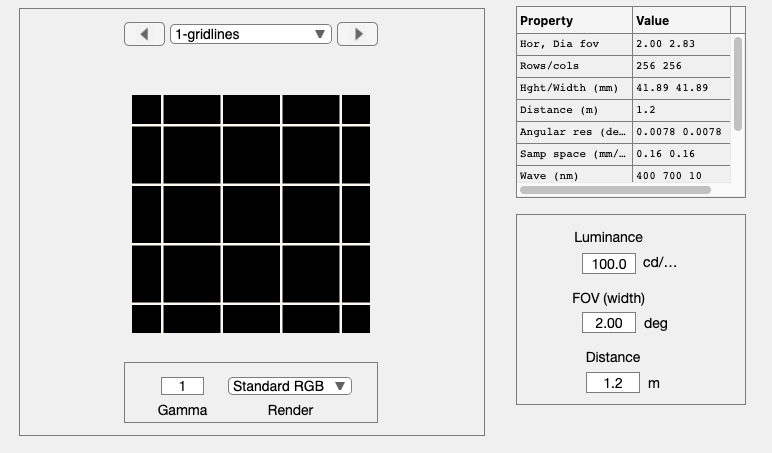

imSize = [256 256];
spacing = 64;
thickness = 3;
scene = sceneCreate('grid lines',imSize,spacing,'ee',thickness);

% We make a small field of view so that we close up view of the details.
scene = sceneSet(scene,'fov',2);

sceneWindow(scene);


oi = oiCreate('psf');

## Example 1: Create a pillbox point spread function

The pillbox was often used in the past because it can be computed very quickly.  It isn't good for much, but I stuck it in here anyway.  Mostly, notice how much blurrier the pillbox is than an Airy pattern with the same disk size.

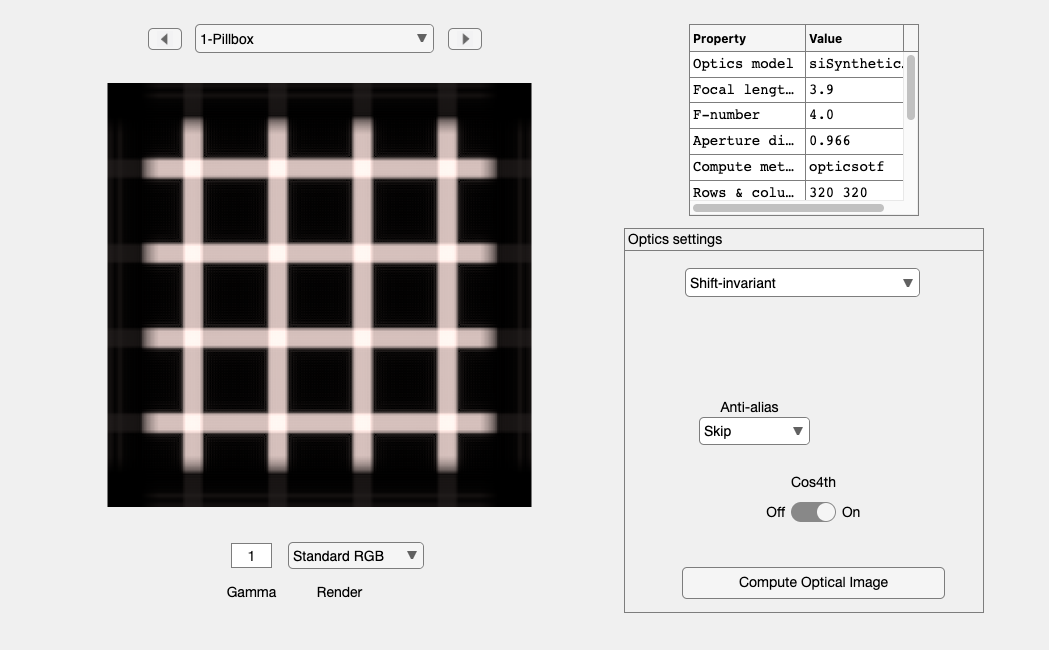


patchSize = airyDisk(700,oiGet(oi,'optics fnumber'),'units','mm');
optics    = siSynthetic('pillbox',oi , patchSize);

% Attach the optics to the oi (optical image)
oi = oiSet(oi,'optics',optics);

% Setthe model to shift invariant
% oi = oiSet(oi,'optics model','shiftInvariant');

% Apply the optics to the checkerboard scene.
oi = oiCompute(oi,scene);
oi = oiSet(oi,'name','Pillbox');

% Add to the database and show the OI window
oiWindow(oi);


xpsf{1} = oiGet(oi,'optics psf xaxis');

## Example 2: A wavelength-dependent Lorentizian

The Lorentzian gamma parameter seems to run nicely from 1 to 10 or so on this support. Log spacing converts better to spread than linear spacing.

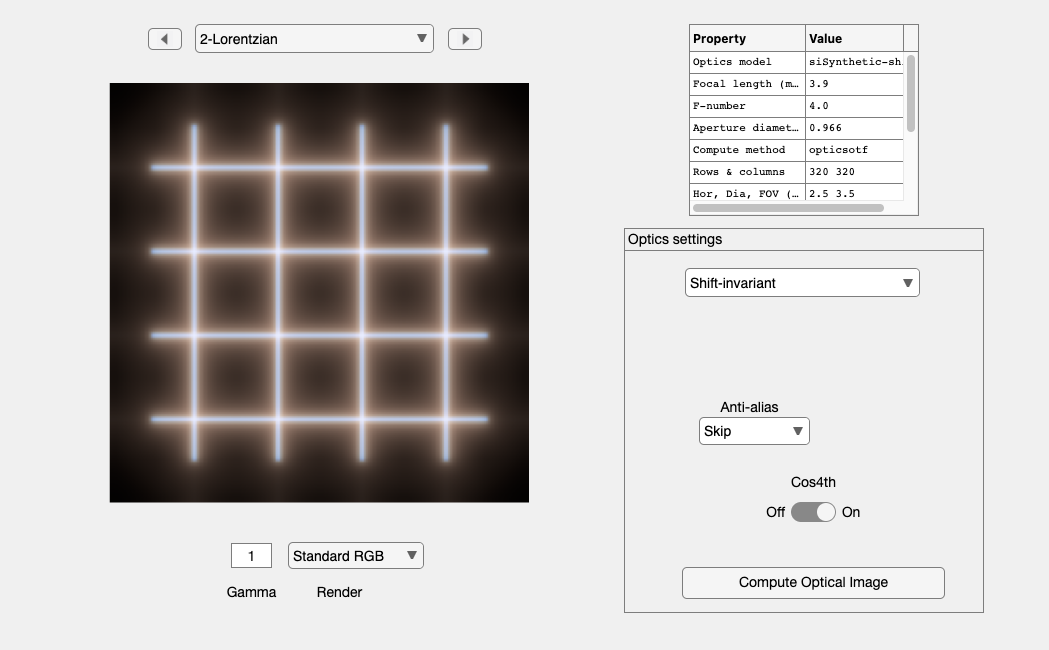

psfType    = 'lorentzian';
nWave      = oiGet(oi,'nwave');
gParameter = logspace(0,1,nWave);
optics     = siSynthetic(psfType,oi,gParameter);

oi = oiSet(oi,'optics',optics);
oi = oiCompute(oi,scene);
oi = oiSet(oi,'name','Lorentzian');
oiWindow(oi);

%  psfMovie(optics,ieNewGraphWin);

xpsf{2} = oiGet(oi,'optics psf xaxis');

## Example 3: A circular Gaussian PSF that changes with wavelength

The spread of the Gaussian increases with wavelength, so the long wavelength PSF is much blurrier than the short wavelength PSF.  Look for the color fringing in the oiWindow.

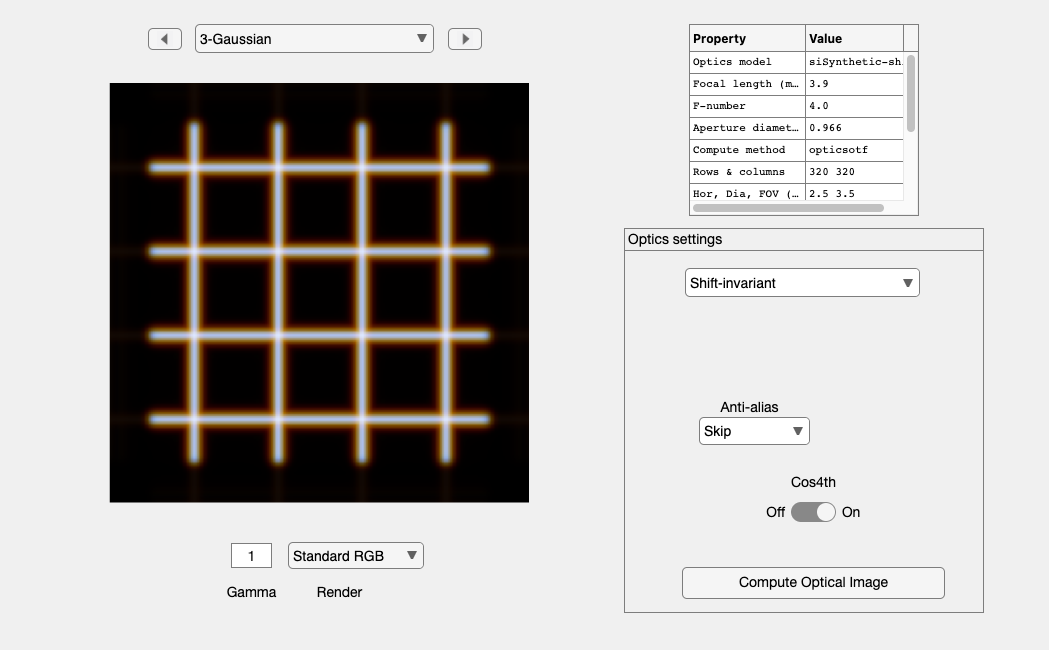

wave    = oiGet(oi,'wave');
psfType = 'gaussian';
waveSpread = 0.5*(wave/wave(1)).^3;

% Make point spreads with a circular bivariate Gaussian
xyRatio = ones(1,length(wave));

% Now call the routine with these parameters
optics  = siSynthetic(psfType,oi,double(waveSpread),xyRatio);
oi      = oiSet(oi,'optics',optics);

% Here is the rest of the computation, as above
oi  = oiSet(oi,'optics model','shiftInvariant');
scene   = ieGetObject('scene');
oi      = oiCompute(oi,scene);

oi = oiSet(oi,'name','Gaussian');
oiWindow(oi);


xpsf{3} = oiGet(oi,'optics psf xaxis');

## Diffraction limited

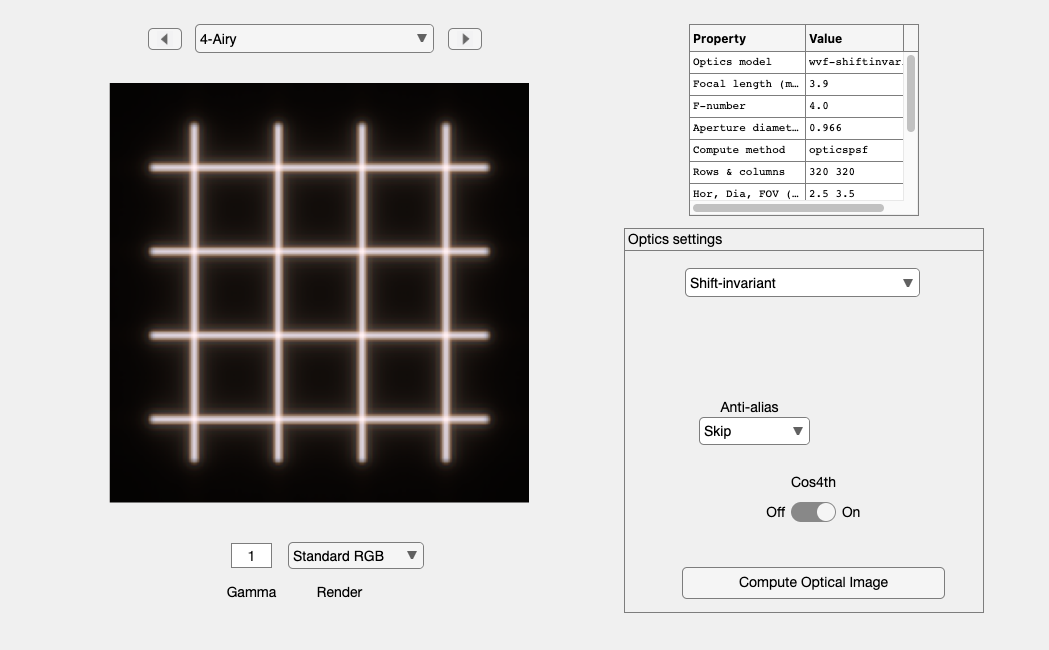

oi = oiCreate('wvf');
oi      = oiCompute(oi,scene);
oi = oiSet(oi,'name','Airy');
oiWindow(oi);


xpsf{4} = oiGet(oi,'optics psf xaxis');

## Compare multiple oi images

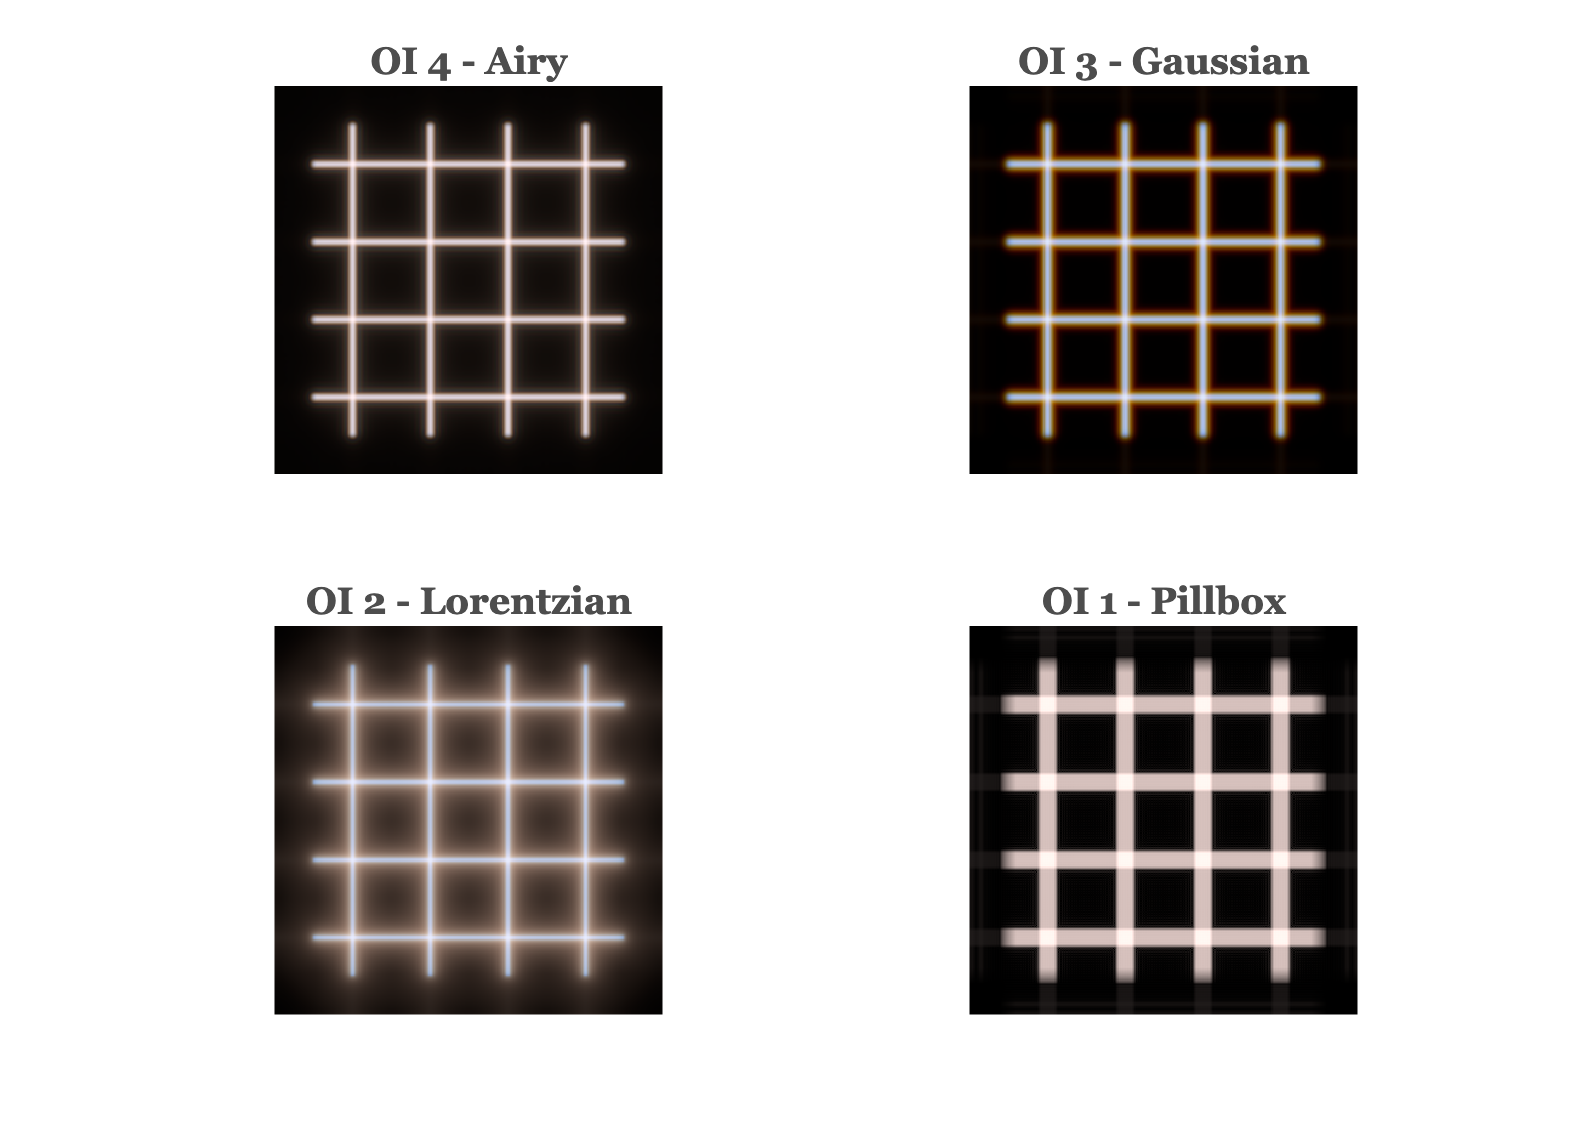

lst = [4,3,2,1];
[~,hdl] = imageMultiview('oi',lst,1);

% exportgraphics(hdl,fullfile(imgDir,'optics-siKernels-image.png'));

## Plot the cross sections

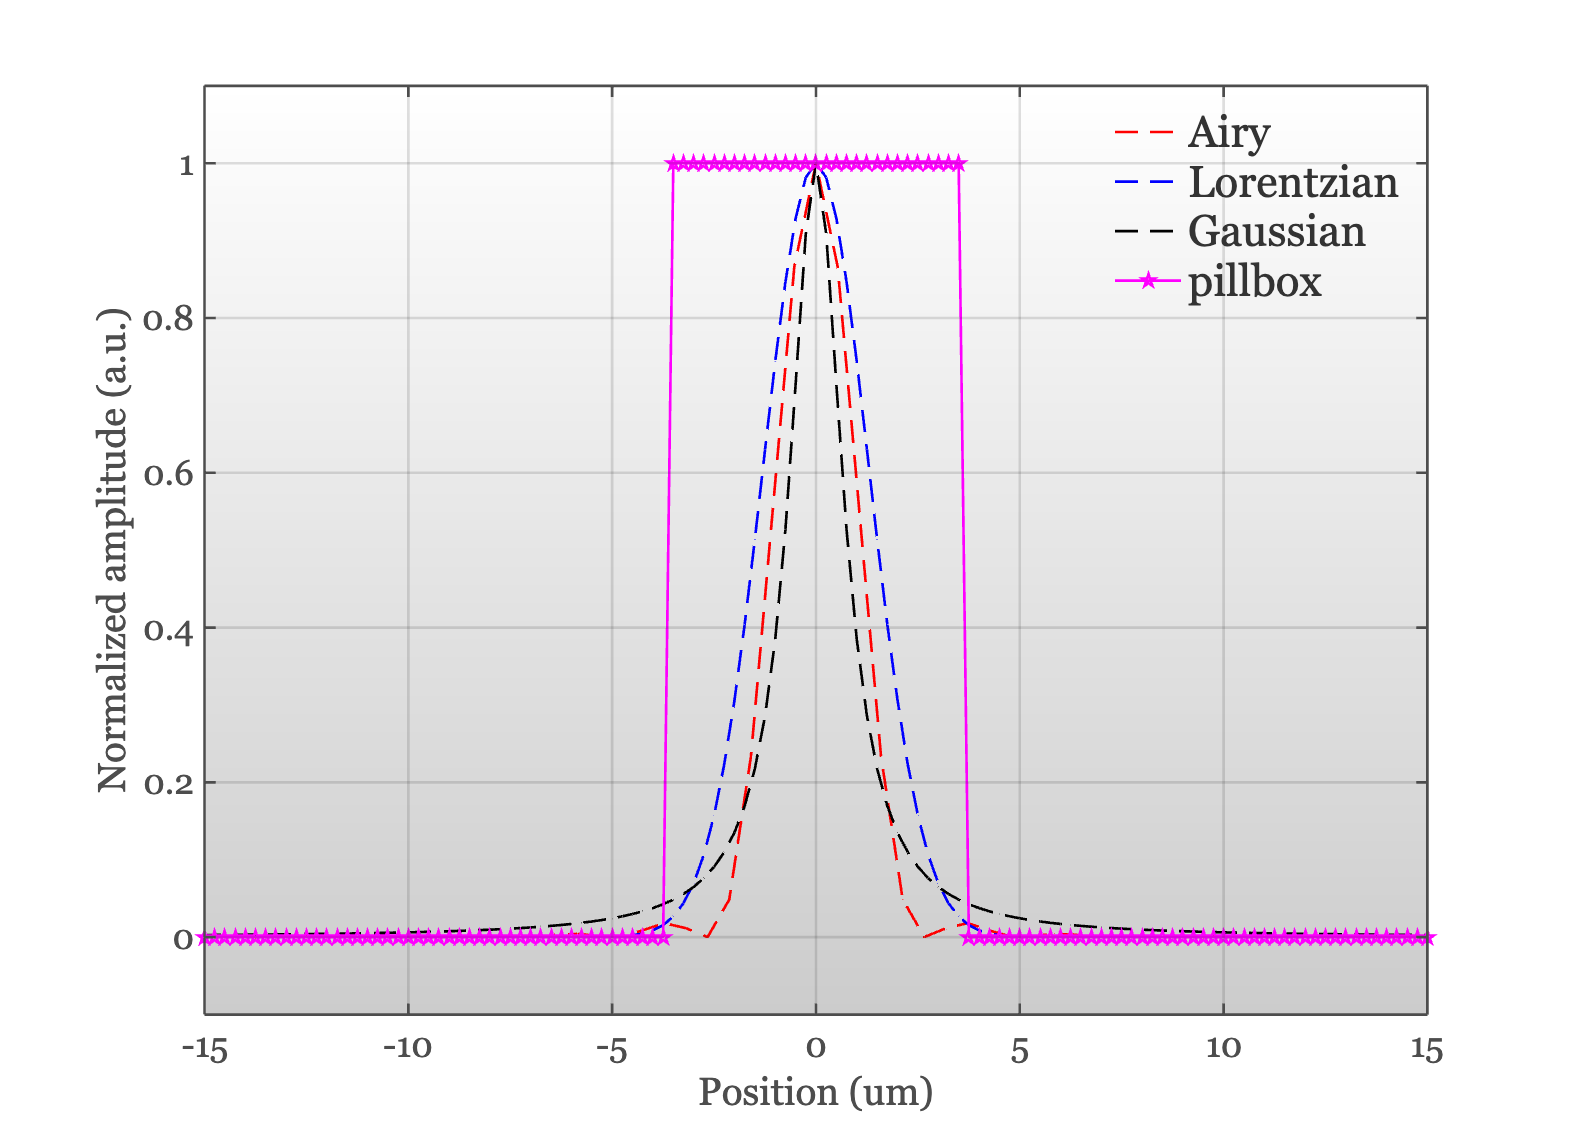

sym = {'r--','b--','k--','p-'};
hdl = ieFigure;

% DL, Gauss, Lorenz, Pillbox

h = [];
for ii=1:numel(lst)
    h(ii) = plot(xpsf{lst(ii)}.samp,xpsf{lst(ii)}.data/max(xpsf{lst(ii)}.data),sym{ii}); 
    hold on; grid on;
end
set(gca,'xlim',[-15 15]);
set(gca,'ylim',[-0.1 1.1]);

iePlotShadeBackground(hdl.CurrentAxes);

leg = legend(h(1:4),{'Airy','Lorentzian','Gaussian','pillbox'});
leg.FontSize = 20;
xlabel('Position (um)'); ylabel('Normalized amplitude (a.u.)')

% exportgraphics(hdl,fullfile(imgDir,'optics-siKernels-graph.png'));

fprintf('Airy disk radius is %f um\n',patchSize*1e3);

Airy disk radius is 3.416000 um


## A shift invariant bivariate normal psf

This example makes a Gaussian that is narrow in one direction and broad in the other. This orientation difference is called *astigmatism*.

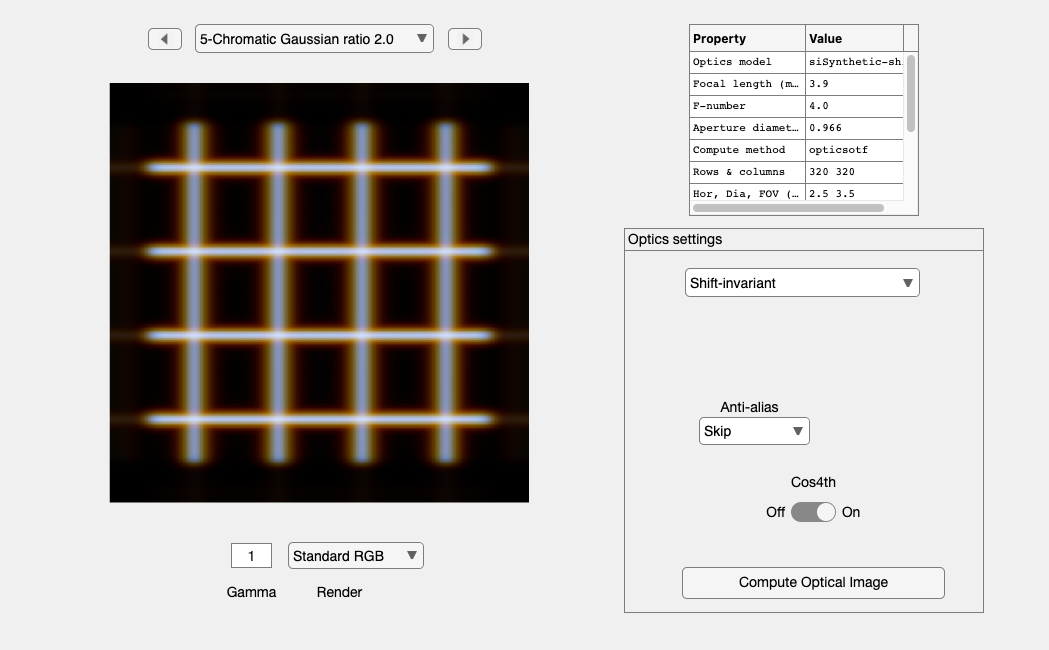

oi = oiCreate('psf');

wave    = oiGet(oi,'wave');
psfType = 'gaussian';
waveSpread = 0.5*(wave/wave(1)).^3;

% Make point spreads with a bivariate Gaussian.
% If sFactor < 1, then x (horizontal) is sharper.
% If sFactor > 1, then y (vertical)   is sharper.
sFactor = 2;
xyRatio = sFactor*ones(1,length(wave));

% Now call the routine with these parameters
optics  = siSynthetic(psfType,oi,double(waveSpread),xyRatio);
oi      = oiSet(oi,'optics',optics);

% Here is the rest of the computation, as above
oi  = oiSet(oi,'optics model','shiftInvariant');
scene   = ieGetObject('scene');
oi      = oiCompute(oi,scene);

oi = oiSet(oi,'name',sprintf('Chromatic Gaussian ratio %.1f',sFactor));
oiWindow(oi);


xpsf{5} = oiGet(oi,'optics psf xaxis');

## Show the PSF as a function of wavelength in a movie

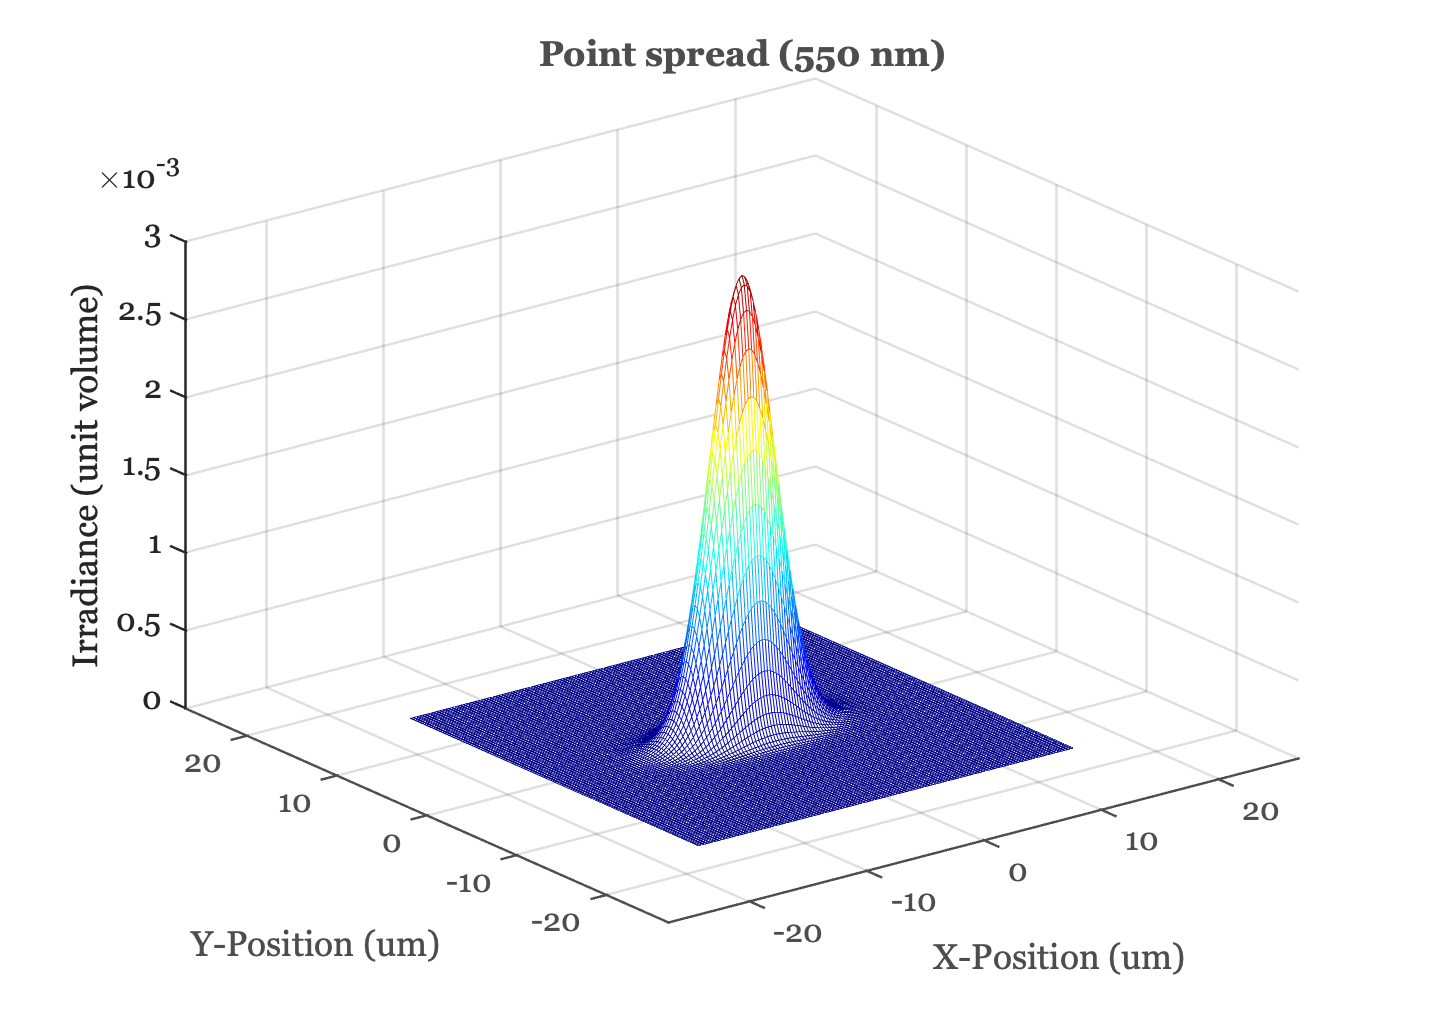

oiPlot(oi,'psf',550);

% psfMovie(oiGet(oi,'optics'),ieFigure,0.1);

## Compare a horizontal and vertical line

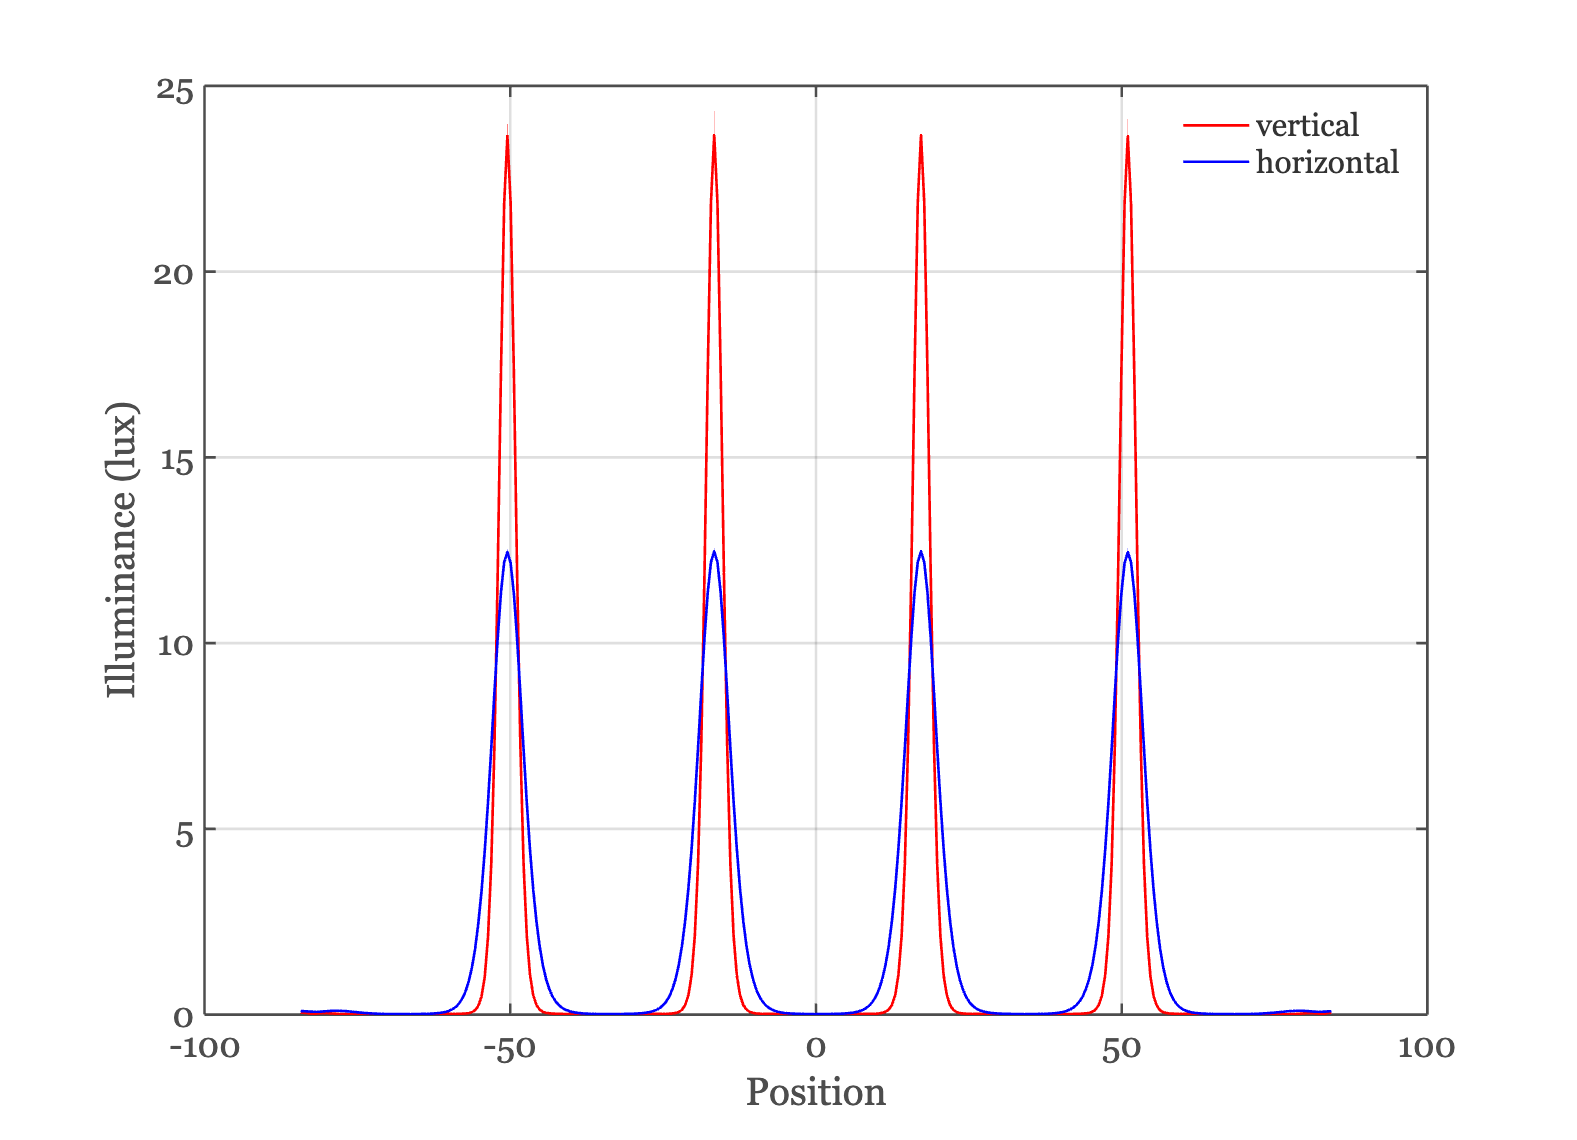

% Find the xy coordinates of the middle of the data
sz = oiGet(oi,'size');
[~,center] = getMiddleMatrix(oiGet(oi,'photons'),sz);
xyMiddle = center(1:2);

% Plot through the middle
vData = oiPlot(oi,' illuminance vline',xyMiddle,'nofigure');
hData = oiPlot(oi,' illuminance hline',xyMiddle,'nofigure');

ieFigure;
plot(vData.pos,vData.data,'r-',hData.pos,hData.data,'b-');
grid on; xlabel('Position'); ylabel('Illuminance (lux)');
legend({'vertical','horizontal'});

## Plot the spectral irradiance of a horizontal and a vertical line

You can see the wavelength-dependent blur in this rendition with space on one axis and wavelength on the other. The spread of the light is smaller at the short wavelengths and increases at the long wavelengths.

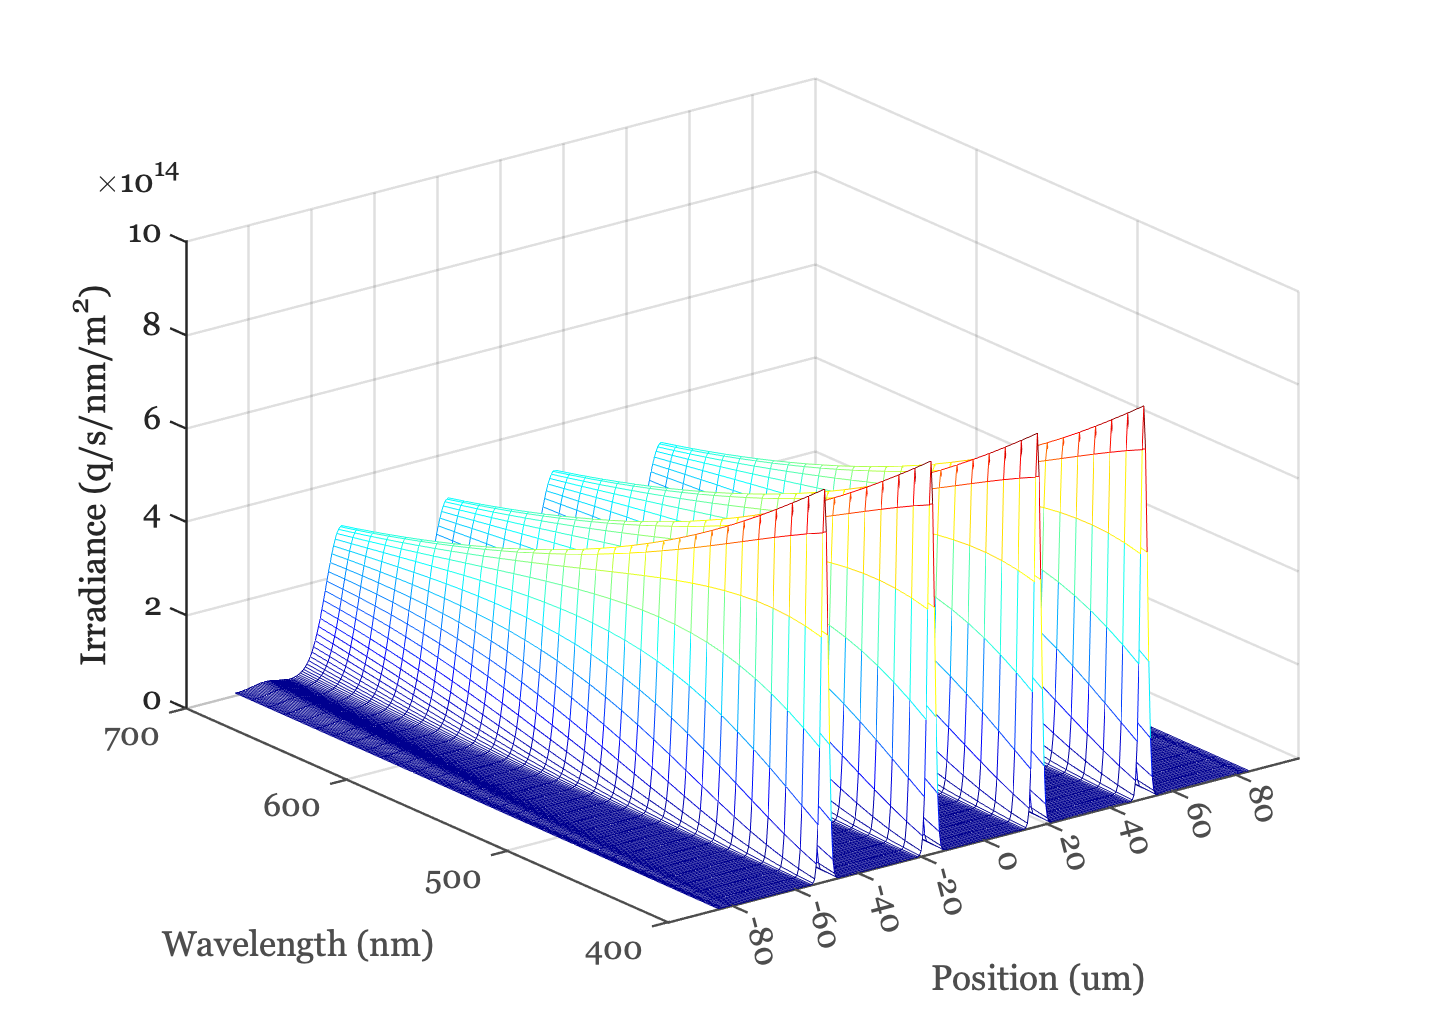

oiPlot(oi,' irradiance hline',center); colormap('jet');